# Final Lab: Auto Tune

Notes / what I am learning: 

- Fundamental frequency is different than the most prominent frequency

- 'findpeaks' - find local maxima

- Autocorrelation is a method of signal processing where you compare, a signal with a shifted version of itself. This is to find the fundamental frequency of the signal.

- DC offset is a bias from zero caused from electronics

- 440 is an A, which is typically the base note for the math

% -------------------------------
% Final Lab: Auto Tune
% -------------------------------

% Record voice
myVoice = audiorecorder;
myVoice.StartFcn = 'disp(''Start speaking.'')';
myVoice.StopFcn  = 'disp(''End of recording.'')';
recordblocking(myVoice, 5);

Start speaking.



% Extract data and sample rate
data = getaudiodata(myVoice);
fs = myVoice.SampleRate;

% Play recording
player = audioplayer(data, fs);
playblocking(player);




% Test splitting the audio apart and putting it back together
% Length of one chunk in samples (20 ms)
chunk_dur = 0.020;              % 20 ms
chunk_len = round(chunk_dur * fs);

% Number of chunks
num_chunks = ceil(length(data) / chunk_len);

% Preallocate cell array to hold chunks
chunks = cell(1, num_chunks);

% Split audio into 20 ms chunks
for k = 1:num_chunks
    idx_start = (k-1)*chunk_len + 1;
    idx_end   = min(k*chunk_len, length(data)); % don't exceed length
    chunks{k} = data(idx_start:idx_end);
end

% Splice chunks back together
reconstructed = vertcat(chunks{:});

% Play reconstructed audio
player2 = audioplayer(reconstructed, fs);
playblocking(player2);




% Remove DC offset
data = data - mean(data);

% ---- Fundamental frequency via autocorrelation ----
[r, time_shifts] = xcorr(data, 'coeff');      % do autocorrelation
r = r(time_shifts >= 0);
time_shifts = time_shifts(time_shifts >= 0);

% Limit to human voice pitch range: 50–1000 Hz
minLag = floor(fs/1000);   % max frequency = 1000 Hz
maxLag = ceil(fs/50);      % min frequency = 50 Hz
r_valid = r(minLag:maxLag);
time_shifts_valid = time_shifts(minLag:maxLag);

% Find lag with maximum autocorrelation → fundamental period
[~, idx] = max(r_valid);
fundamental_period = time_shifts_valid(idx);
fundamental_freq = fs / fundamental_period;

disp(['Estimated fundamental frequency: ', num2str(fundamental_freq), ' Hz']);

Estimated fundamental frequency: 156.8627 Hz



% Map to closest musical note
A4 = 440;
notes = -80:80;
freqs = A4 * 2.^(notes/12);
freqs = freqs(freqs <= 1000);

[~, idx] = min(abs(freqs - fundamental_freq));
closest_pitch = freqs(idx);
disp(['Closest musical pitch: ', num2str(closest_pitch), ' Hz']);

Closest musical pitch: 155.5635 Hz


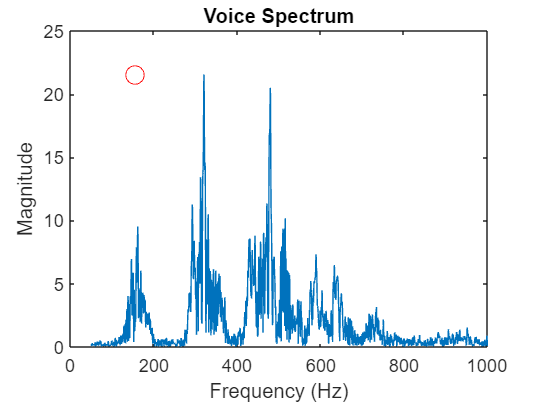


% Plot spectrum and mark fundamental
% Plot spectrum like first graph
Y = fft(data);
N = length(data);
f = (0:N-1)*(fs/N);
f_min = 50;
f_max = 1000;
valid_freqs = (f >= f_min) & (f <= f_max);
figure;
plot(f(valid_freqs), abs(Y(valid_freqs)));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Voice Spectrum');
hold on;
plot(fundamental_freq, max(abs(Y)), 'ro', 'MarkerSize',10);  % mark fundamental


% ---- Play generated sine wave at fundamental frequency ----
fs_play = 8000;   % playback sample rate
T = 2;            % duration in seconds
t = 0:1/fs_play:T;
y = 0.5 * sin(2*pi*fundamental_freq*t);   % sine wave
sound(y, fs_play);
disp('done');

done
